## Here is how we can see the relationship between signal density and variance:

When we look at the delta mu vector, we can view it as having two types of distributions, one discrete and one continuous.

C = Cloud(69);

Total trials: 371	Throwing away 0	keeping 371
Median index to 50% is 21


delta_mu = C.dmus{10};

### The discrete distribution

The discrete distribution tells us how the total signal is spread across the neurons. The values of this distribution are the neurons themselves and the probability mass is found in signal_direction.^2 . We characterize this discrete distribution by its PR.

In code we can express this as:

signal_direction = delta_mu ./ sqrt(sum(delta_mu.^2));
plot(sort(signal_direction.^2));
xlabel 'Neurons (sorted)'
ylabel 'Probability (adds to 1)'


PR = 1/length(delta_mu) * 1/sum(signal_direction.^4)

PR = 0.1579

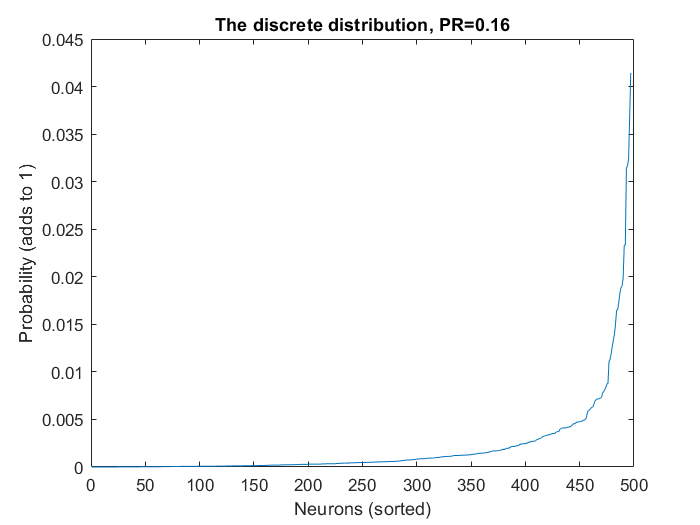


title(sprintf('The discrete distribution, PR=%.2f', PR));

We can rewrite it as:

PR = 1/length(delta_mu) * sum(delta_mu.^2)^2 / sum(delta_mu.^4)

PR = 0.1579

And rewriting the sums with means it is:

PR = mean(delta_mu.^2)^2 / mean(delta_mu.^4)

PR = 0.1579

### The continuous distribution

However, there is another distribution hiding here. The function mean is computing the mean of some distribution for which every sample is a signal quantity delta_mu.^2 and every neuron provides one sample. We don't have the probability density of this continuous distribution, only a set of samples, but we can compute a histogram and an empirical CDF:

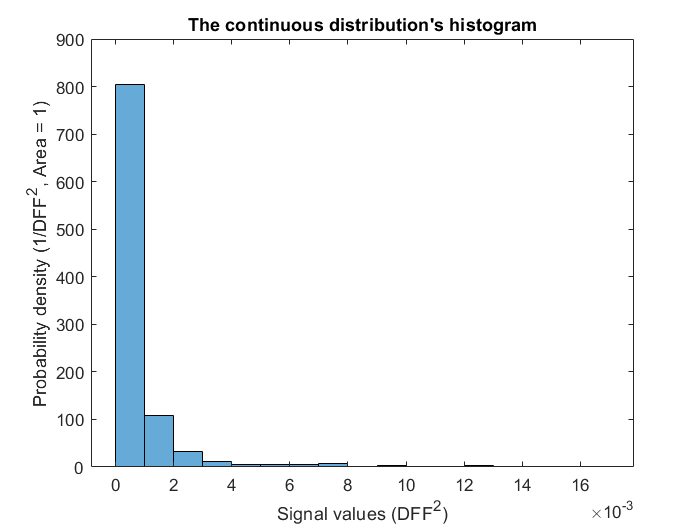

histogram(delta_mu.^2, 'Normalization','pdf');
xlabel 'Signal values (DFF^2)'
ylabel 'Probability density (1/DFF^2, Area = 1)'
title 'The continuous distribution''s histogram'

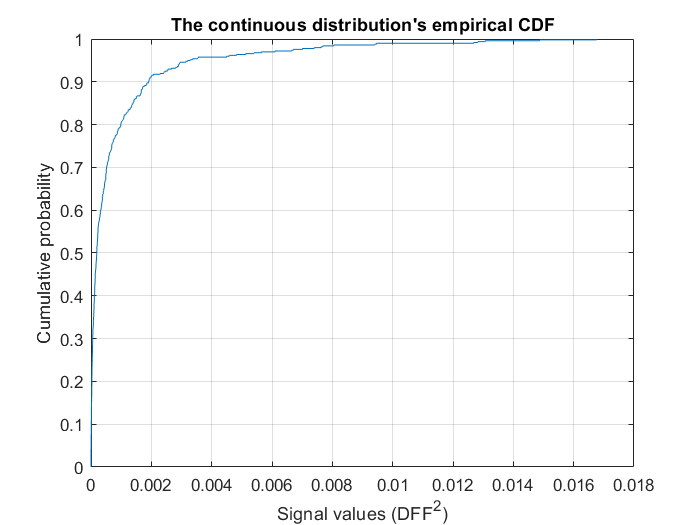

cdfplot(delta_mu.^2);
xlabel 'Signal values (DFF^2)'
ylabel 'Cumulative probability'
title 'The continuous distribution''s empirical CDF'

The ordinary variance of this distribution is as follows:

linear_scale_variance = mean(delta_mu.^4) - mean(delta_mu.^2)^2

linear_scale_variance = 3.5329e-06

This looks very similar to the formula for the PR except that the order is flipped and there is subtraction instead of division.

Now let's check what happens to a log-normal random variable X ~ lognormal(mu, sigma^2) if we compute the formula <X>^2/<X^2>:

mu = mean(log(delta_mu.^2))

mu = -8.8081

sigma = std(log(delta_mu.^2))

sigma = 2.2640

X = exp(sigma*randn(500,1) + mu); %using 500 samples
formula = mean(X)^2 / mean(X.^2)

formula = 0.0380

First let's convert mean(X^2) to var(X,1) + mean(X)^2:

formula = mean(X)^2 / ( var(X,1) + mean(X)^2) % = 

formula = 0.0380

formula = 1 / (var(X,1)/mean(X)^2 + 1)

formula = 0.0380

For the log-normal variable, mean(X) = exp(mu + sigma^2/2) and var(X) = (exp(sigma^2) - 1)*mean(X)^2. When we plug that in we see that (using the true value of sigma):

formula_exact = 1 / ( exp(sigma^2)-1  + 1) % = 

formula_exact = 0.0059

formula_exact = 1/exp(sigma^2) % = 

formula_exact = 0.0059

formula_exact = exp(-sigma^2)

formula_exact = 0.0059

And using the estimated value of sigma:

estimated_sigma = std(log(X))

estimated_sigma = 2.2804

formula_estimated = 1 / ( exp(estimated_sigma^2)-1  + 1) % = 

formula_estimated = 0.0055

formula_estimated = 1/exp(estimated_sigma^2) % = 

formula_estimated = 0.0055

formula_estimated = exp(-estimated_sigma^2)

formula_estimated = 0.0055

It is important to note that sigma^2 is the variance in the log-domain. So if the continuous distribution of signal amounts (delta_mu.^2) over neurons is log-normal, then the PR of the discrete distribution of signal over neurons is exactly determined by the log-variance as exp(-sigma^2).

#### Estimation bias problems

Due to bias, the PR formula and the exp(-sigma^2) formulas can differ when the sample size is limited. The rectangle shows our range of sample size (i.e. the number of neurons per session). This is the case even when the true distribution is log-normal, as in this simulation.

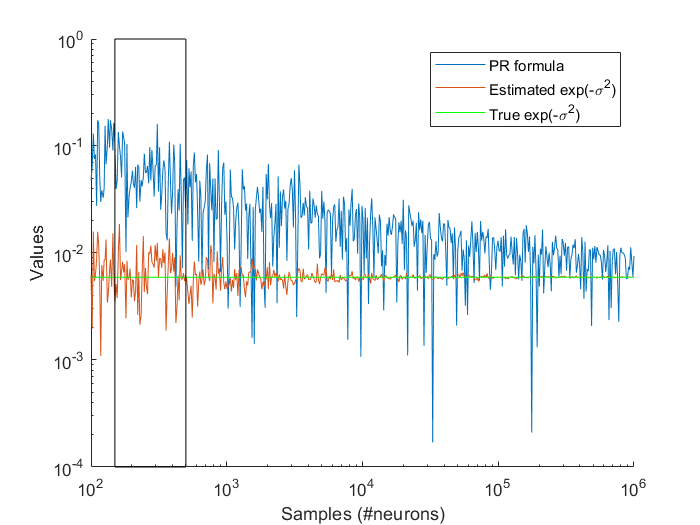

samples = round(logspace(2,6,500));
[pr_value, es_value] = deal(zeros(size(samples)));
pr = @(x) mean(x).^2 ./ mean(x.^2);
es = @(x) exp(-var(log(x)));
es_true = exp(-sigma^2);
for i = 1:numel(samples)
    X = exp(sigma*randn(samples(i),1) + mu);
    pr_value(i) = pr(X);
    es_value(i) = es(X);
end
figure; hold on;
plot(samples, pr_value);
plot(samples, es_value);
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');
l_ = refline(0, es_true); l_.Color = 'g';
legend 'PR formula' 'Estimated exp(-\sigma^2)' 'True exp(-\sigma^2)'
xlabel 'Samples (#neurons)'
ylabel 'Values'
yl_ = ylim;
rectangle('Position', [150 yl_(1) (500-150) diff(yl_)]);

Nevertheless, even with only 500 samples, the PR formula and the estimated exp(-sigma^2) are still correlated.

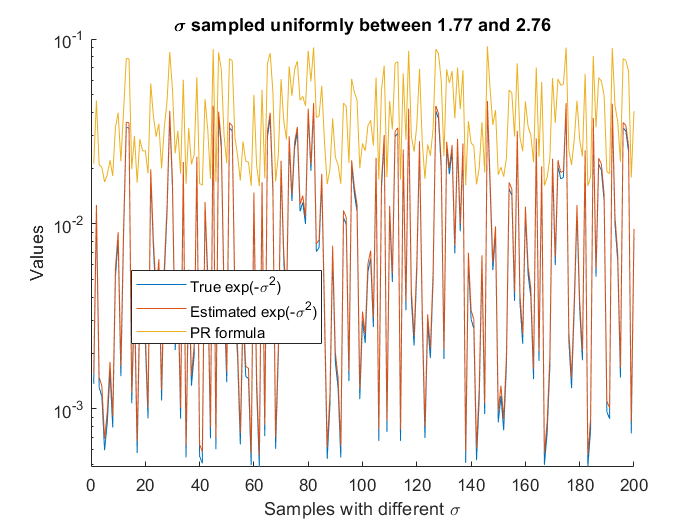

mu = mean(log(delta_mu.^2));
sigma = std(log(delta_mu.^2)) + rand(1,200) - 0.5;
X = exp( sigma .* randn(500,1) + mu);
figure; hold on; 
true_ES = exp(-sigma.^2);
estimated_ES = es(X);
PR_formula = pr(X);
plot(true_ES); plot(estimated_ES); plot(PR_formula); 
set(gca, 'YScale', 'log');
legend 'True exp(-\sigma^2)' 'Estimated exp(-\sigma^2)' 'PR formula'
legend Location best
xlabel 'Samples with different \sigma'
ylabel 'Values'
title(sprintf('\\sigma sampled uniformly between %.2f and %.2f', min(sigma), max(sigma)));

Despite the values of the PR formula being different, the correlation with the true and estimated exp(-sigma^2) is still very high.

correlations = corrcoef([true_ES; estimated_ES; PR_formula]')

correlations =     1.0000    1.0000    0.9868
    1.0000    1.0000    0.9879
    0.9868    0.9879    1.0000


one_minus_correlations = 1 - correlations

one_minus_correlations =          0    0.0000    0.0132
    0.0000         0    0.0121
    0.0132    0.0121         0


### Summary

The formula for PR is a biased estimator for the inverse exponential of the log domain variance, assuming a log-normal distribution. The delta_mu.^2 values are almost log-normal except for a fat tail in the negative direction:

figure;
mu = mean(log(delta_mu.^2))

mu = -8.8081

sigma = std(log(delta_mu.^2))

sigma = 2.2640

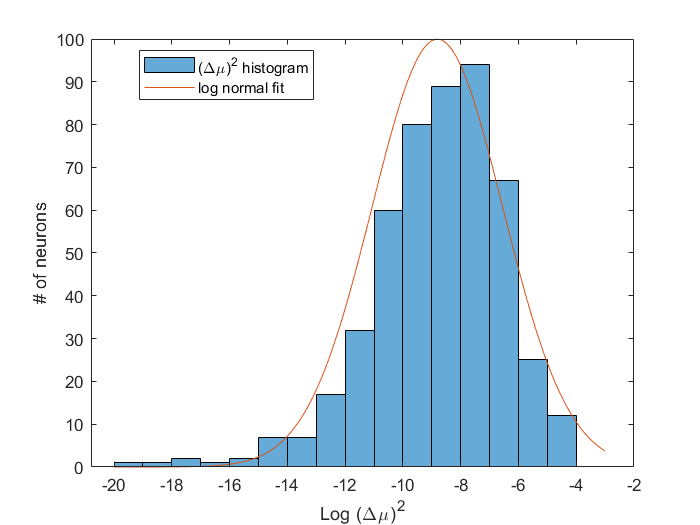

histogram(log(delta_mu.^2), 'Normalization','count');
hold on;
x = linspace(-20,-3,100);
plot(x, 100*exp(-(x-mu).^2 ./ (2.*sigma.^2)));
xlabel 'Log (\Delta\mu)^2'
ylabel '# of neurons'
legend '(\Delta\mu)^2 histogram' 'log normal fit' Location best

The fat tail most likely causes the Anderson-Darling test to declare that this is not log normally distributed. The null hypothesis is that the data is normal, and it is rejected in this case when I feed in the log of the signal:

[h, p] = adtest(log(delta_mu.^2))

h = logical
   1


p = 5.0000e-04

I haven't proven it, but I think that the PR formula is a more robust option than computing exp(-var(log(data))) when the data is not log-normal due to the non-robustness of the variance estimator and the fact that log will amplify very low numbers like exp(-20) which are probably actually 0. The PR formula will gracefully handle 0 values even when the log function in exp(-var(log(data))) will not.